smoothwidth = 3;
smoothtype =1;
x = 1:100

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


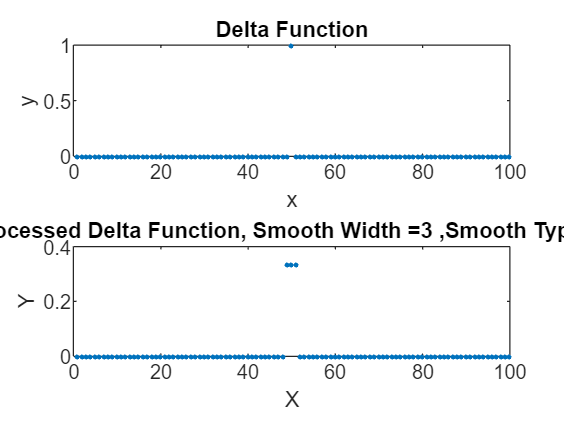

delta = zeros(size(x));
delta(round(size(delta)/2)) = 1;
delta(1) = 0;
processdelta = fastsmooth(delta,smoothwidth,smoothtype);
subplot(2,1,1)
plot(x,delta,'.')
xlabel('x');ylabel('y');
title("Delta Function")
subplot(2,1,2)
plot(x,processdelta,".")
title(['Processed Delta Function, Smooth Width =', num2str(smoothwidth), ' ,Smooth Type =',num2str(smoothtype)'])

xlabel('X');ylabel('Y');